# **Course Project in Computational Mathematics**

## **Direct fast method for solving the SoLE of the anisotropic diffusion equation** 

Consider the anisotropic diffusion equation supplemented by the Dirichlet condition in the unit square. 

## 
$$-\frac{\partial^2 }{\partial x^2 }u\left(x,y\right)-3\;\frac{\partial^2 }{\partial y^2 }u\left(x,y\right)\;+u\left(x,y\right)=\sin \left(\pi x\right),\;\textrm{in}\;V=\left(0,1\right)\;\&\;{\;u\left(x,y\right)\left|\right.}_G =0\;$$


clc;
clear all;
steps = 100; % quantity of steps for grid
step = 1 / steps;  % step of grid
checkTime = zeros(1, 2);
tic;

### Exact solution

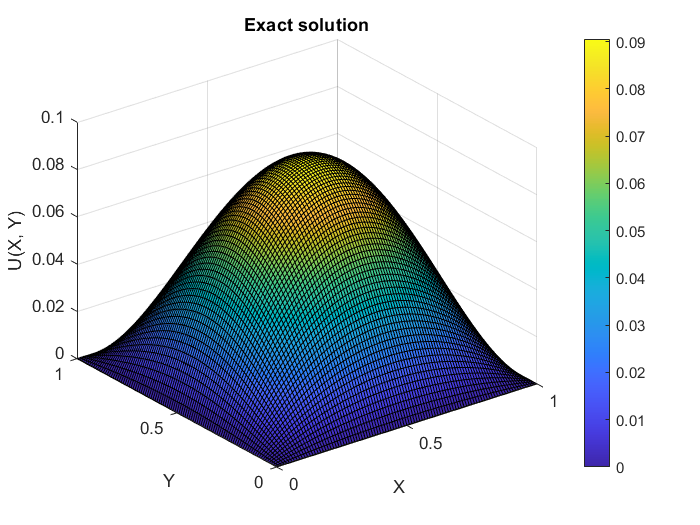

Const = (3 * cosh(sqrt((pi.^2 + 1) / 3)) / (pi.^2 + 1) - 3 / (pi.^2 + 1)) / sinh(sqrt((pi.^2 + 1) / 3));
U = zeros(steps + 1, steps + 1);
for ix = 1 : steps + 1
    for iy = 1 : steps + 1
        U(ix, iy) = sin(pi * (ix - 1) * step) * (-3 * cosh((iy - 1) * step * sqrt((pi.^2 + 1) / 3)) / (pi.^2 + 1) + 3 / (pi.^2 + 1) + Const * sinh((iy - 1) * step * sqrt((pi.^2 + 1) / 3)));
    end
end
%% for matrix version
% Ucur = zeros(1, (steps - 1) * (steps - 1));
% for ix = 1 : steps - 1
%     for iy = 1 : steps - 1
%         Ucur(1, (iy - 1) * (steps - 1) + ix) = sin(pi * ix * step) * (-3 * cosh(iy * step * sqrt((pi.^2 + 1) / 3)) / (pi.^2 + 1) + 3 / (pi.^2 + 1) + Const * sinh(iy * step * sqrt((pi.^2 + 1) / 3)));
%     end
% end
[X, Y] = meshgrid(0 : step : 1, 0 : step : 1);
surf(X, Y, U);
title('Exact solution');
ylabel('Y'), xlabel('X'), zlabel('U(X, Y)');
colorbar;

Double fast sine conversion 

%% constructing right part of equation
fSin = zeros((steps - 1), (steps - 1));
for iy = 1 : steps - 1
    for ix = 1 : steps - 1
%         fSin(ix, iy) = 32 * step.^3 * (ix * (1 - ix * step) + iy * (1 - iy * step));
%         fSin(ix, iy) = step.^4 * ix.^2;
        fSin(ix, iy) = 3 * step.^2 * sin(pi * ix * step);
    end
end
checkTime(1,1) = toc;
% multiply by W^(-1)
fSin = fSin';
uSin = idst(fSin);
uSin = uSin';
uSin = idst(uSin) / step.^2;

%% reverse matrix of diag(Spectrum)
lambda = zeros((steps - 1), (steps - 1));
for m = 1 : steps - 1
    for k = 1 : steps - 1
        lambda(k, m) = step.^2 / (4 * (sin(pi * k * step * 0.5)).^2 + 12 * ...
        (sin(pi * m * step * 0.5)).^2 + step.^2);
    end
end
uSin = lambda .* uSin;

% multiply by W
uSin = uSin';
uSin = dst(uSin);
uSin = uSin';
uSin = dst(uSin);
checkTime(1,2) = toc;
disp("Time for Double fast sine conversion: " ), disp(checkTime(1,2) - checkTime(1,1));

Time for Double fast sine conversion: 
    0.0422



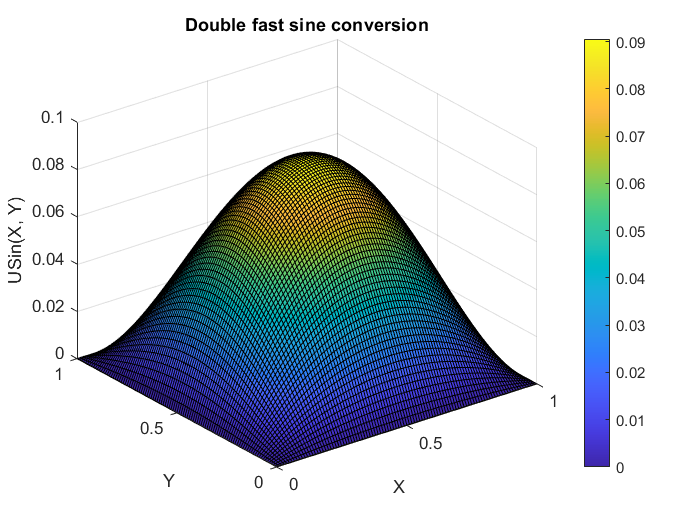


%% plotting solution
USin = zeros(steps + 1, steps + 1);
for iy = 1 : steps - 1
    for ix = 1 : steps - 1
        USin(ix + 1, iy + 1) = uSin(ix, iy);
    end
end
surf(X, Y, USin);
title('Double fast sine conversion');
ylabel('Y'), xlabel('X'), zlabel('USin(X, Y)');
colorbar;

### Jacobi method (Matrix version, very slow)

% %% constructing right part of equation
% fI = zeros(1, (steps - 1) * (steps - 1));
% for iy = 1 : steps - 1
%     for ix = 1 : steps - 1
% %         fI(1, (iy - 1) * (steps - 1) + ix) = 32 * step.^3 * (ix * (1 - ix * step) + iy * (1 - iy * step));
% %         fI(1, (iy - 1) * (steps - 1) + ix) = step.^4 * ix.^2;
%         fI(1, (iy - 1) * (steps - 1) + ix) =  3 * step.^ 2 * sin(pi * ix * step);
%     end
% end
% 
% %% constructing reverse diag part of matrix
% reverseD = zeros(1, (steps - 1) * (steps - 1));
% for m = 1 : steps - 1
%     for k = 1 : steps - 1
%         reverseD(1, (m - 1) * (steps - 1) + k) = 1 / (8  + step.^2);
%     end
% end
% 
% %% constructing other part of matrix
% negative3E = -3 * eye(steps - 1);
% C = zeros(steps - 1);
% for i = 1 : (steps - 1)
%     for j = 1 : (steps - 1)
%         if i - j == 1 || j - i == 1
%             C(i, j) = -1;
%         end
%     end
% end
% A = zeros((steps - 1) * (steps - 1), (steps - 1) * (steps - 1));
% for i = 1 : (steps - 1)
%     for j = 1 : (steps - 1)
%         if i - j == 1 || j - i == 1
%             A((i - 1) * (steps - 1) + 1 : i  * (steps - 1), (j - 1) * (steps - 1) + 1 : j  * (steps - 1) ) = negative3E;
%         end
%         if i == j 
%             A((i - 1) * (steps - 1) + 1 : i  * (steps - 1), (j - 1) * (steps - 1) + 1 : j  * (steps - 1) ) = C;
%         end
%     end
% end
% 
% %% Jacobi method
% uJ = zeros(1, (steps - 1) * (steps - 1));
% while (max(Ucur - uJ) > step^2)
%     uJ = reverseD .* fI - reverseD .* (uJ * A);
% end
% 
% %% plotting solution
% UJ = zeros(steps + 1, steps + 1);
% for iy = 1 : steps - 1
%     for ix = 1 : steps - 1
%         UJ(ix + 1, iy + 1) = uJ(1, (iy - 1) * (steps - 1) + ix);
%     end
% end
% surf(X, Y, UJ);
% title('Jacobi method');
% ylabel('Y'), xlabel('X'), zlabel('UJ(X, Y)');
% colorbar;

### Jacobi method (simplified vresion)

%% constructing right part of equation
fJ = zeros(steps + 1, steps + 1);
for iy = 1 : steps - 1
    for ix = 1 : steps - 1
        fJ(ix + 1, iy + 1) =  3 * step.^ 2 * sin(pi * ix * step);
    end
end

%% Jacobi method
UJ = zeros(steps + 1, steps +1);
itterations = 0;
UJPrev = UJ;
checkTime(1,1) = toc;
while (max(max(U - UJ)) > step^2)
   for iy = 2 : steps
       for ix = 2 : steps
           UJ(ix, iy) = (fJ(ix, iy) + UJPrev(ix - 1, iy) + UJPrev(ix + 1, iy) + 3 * UJPrev(ix, iy - 1) + 3 * UJPrev(ix, iy + 1)) / (8 + step.^2);
       end
   end
   UJPrev = UJ;
   itterations = itterations + 1;
end
checkTime(1,2) = toc;
disp("Time for Double fast sine conversion: " ), disp(checkTime(1,2) - checkTime(1,1));

Time for Double fast sine conversion: 
    2.4895



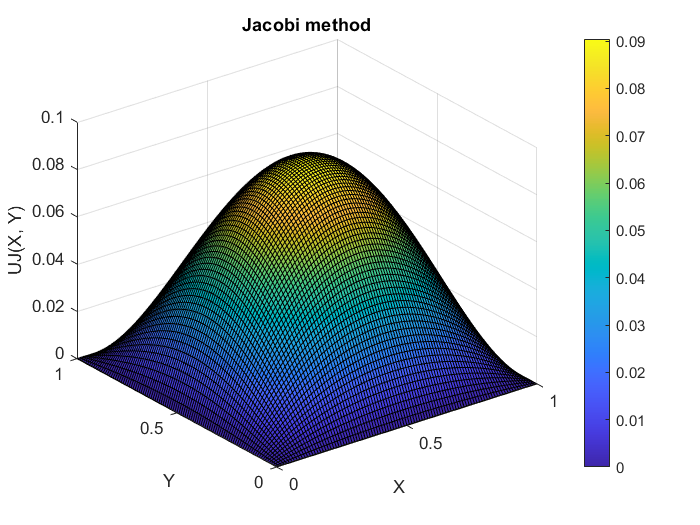

%% plotting solution
surf(X, Y, UJ);
title('Jacobi method');
ylabel('Y'), xlabel('X'), zlabel('UJ(X, Y)');
colorbar;

### Difference between USin & UJ

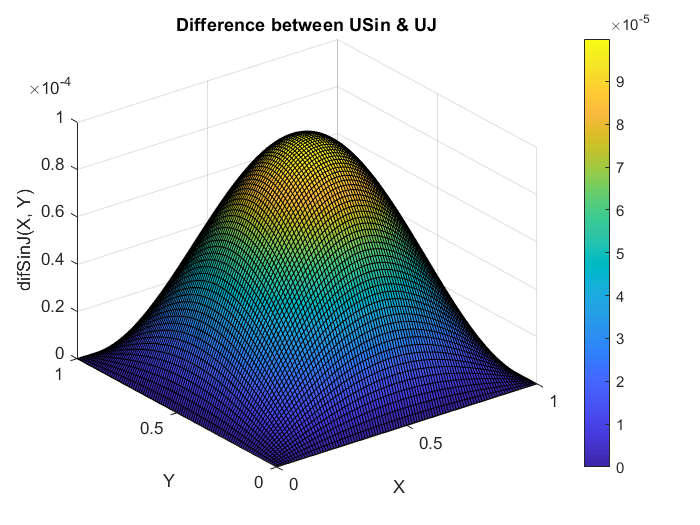

difSinJ = USin - UJ;
surf(X, Y, difSinJ);
title('Difference between USin & UJ');
ylabel('Y'), xlabel('X'), zlabel('difSinJ(X, Y)');
colorbar;

### Difference between U & USin

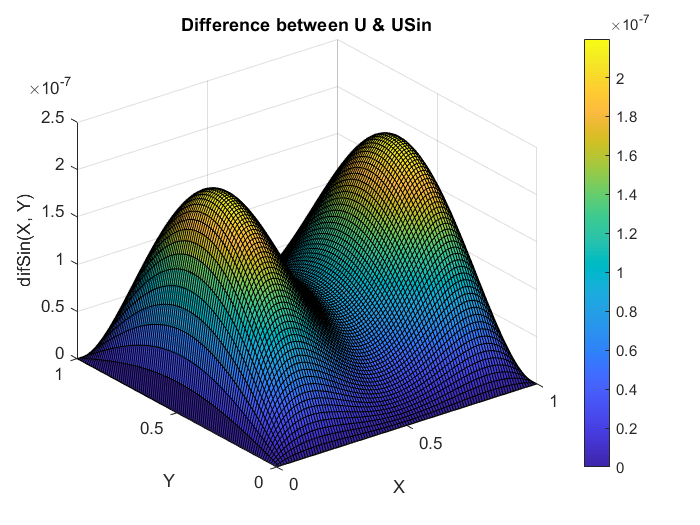

difSin = U - USin;
surf(X, Y, difSin);
title('Difference between U & USin');
ylabel('Y'), xlabel('X'), zlabel('difSin(X, Y)');
colorbar;

### Difference between U & UJ

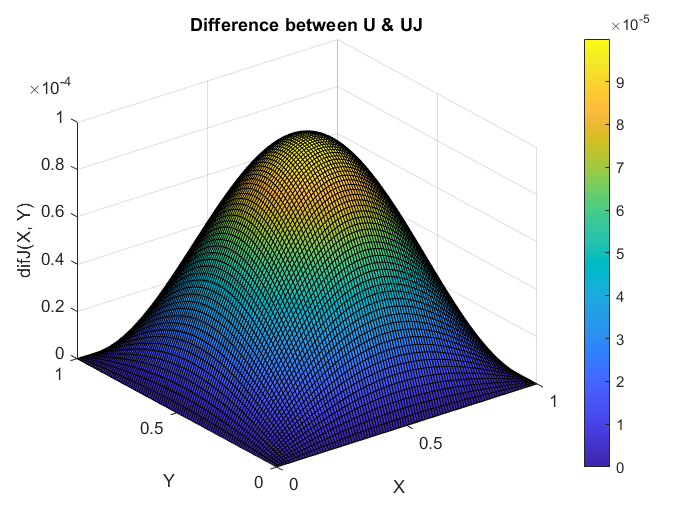

difJ = U - UJ;
surf(X, Y, difJ);
title('Difference between U & UJ');
ylabel('Y'), xlabel('X'), zlabel('difJ(X, Y)');
colorbar;